Cargar conjuntos de datos

% Fijar semilla para reproducibilidad
rng(7);

% Cargar la serie completa de Henon
load('D:/MUBICS/Inteligencia_Computacional/Practicas/P3/Henon/Henon.mat');  % La variable 'x' contiene 300000 muestras

% Seleccionar una posición aleatoria de inicio
N_total = length(x);      % Total de muestras disponibles
N = 1500;                 % Número de muestras a extraer
start_idx = randi([1, N_total - N + 1]);  % Índice de inicio aleatorio

% Seleccionar 1500 muestras consecutivas desde la posición aleatoria
x = x(start_idx : start_idx + N - 1);

summary(x)


x: 1500×1 double

    NumMissing            0  
    Min             -1.2847  
    Median           0.4095  
    Max              1.2729  
    Mean             0.2578  
    Std              0.7207  



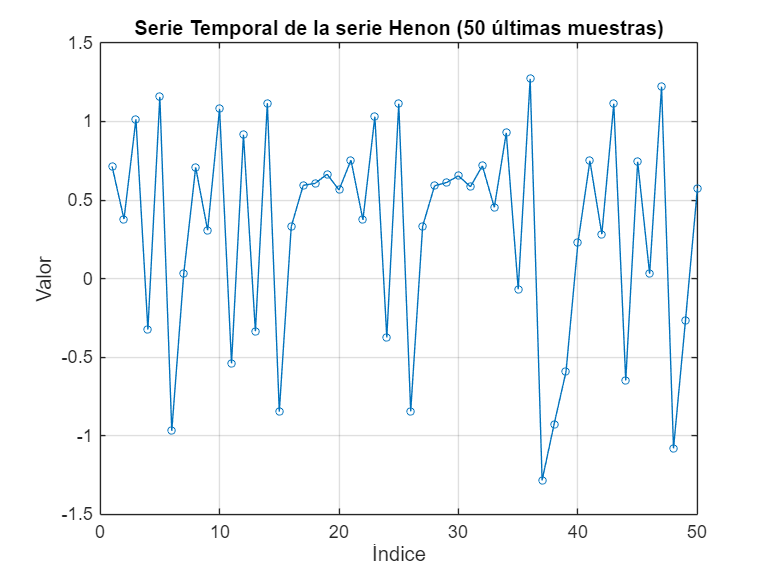

% Tomar las 50 últimas muestras
x_last50 = x(end-49:end);

% Crear gráfico de puntos unidos por líneas (50 últimas muestras)
figure;
plot(x_last50, '-o', 'MarkerSize', 4);
title('Serie Temporal de la serie Henon (50 últimas muestras)');
xlabel('Índice');
ylabel('Valor');
grid on;

Generar 2 conjuntos de datos con distinto tamaño de ventana

% Tamaños de las ventanas
d1 = 5;
d2 = 10;

% Aplicamos la función slidingwindow para cada tamaño de ventana
[INPUTS1, OUTPUTS1] = slidingwindow(x, d1);
[INPUTS2, OUTPUTS2] = slidingwindow(x, d2);

% Mostramos las dimensiones para verificar
disp("Conjunto 1:");

Conjunto 1:


disp(size(INPUTS1));

        1495           5



disp(size(OUTPUTS1));

        1495           1




disp("Conjunto 2:");

Conjunto 2:


disp(size(INPUTS2)) 

        1490          10



disp(size(OUTPUTS2))

        1490           1



Entrenamiento de los SVMs para el primer conjunto de datos con tamaño de ventana 5  (k-fold cross validation, Z-score, MSE/RMSE/MAE)

function [metricsSVM, combinaciones] = get_metricsSVM(INPUTS, OUTPUTS, boxConstraint, kernelFunctions, number_reps, K)

    % Combinaciones
    [BC, KF] = ndgrid(boxConstraint, 1:length(kernelFunctions));
    combinaciones = [BC(:), KF(:)];
    numCombinaciones = size(combinaciones, 1);
    
    % Generar estructura para almacenar métricas
    metricsSVM = struct('MSE', zeros(K, numCombinaciones, number_reps), ...
                        'RMSE', zeros(K, numCombinaciones, number_reps), ...
                        'MAE', zeros(K, numCombinaciones, number_reps));
    
    % Datos a usar
    X_total = INPUTS;  
    Y_total = OUTPUTS;
    
    for modelIdx = 1:numCombinaciones
        c = combinaciones(modelIdx, 1);
        kernelIdx = combinaciones(modelIdx, 2);
        kernel = kernelFunctions{kernelIdx};
    
        for rep = 1:number_reps
            cv = cvpartition(size(X_total,1), 'KFold', K);
    
            for fold = 1:K
                idxTrain = training(cv, fold);
                idxTest = test(cv, fold);
    
                X_train = X_total(idxTrain, :);
                Y_train = Y_total(idxTrain, :);
                X_test = X_total(idxTest, :);
                Y_test = Y_total(idxTest, :);
    
                % Entrenar SVM de regresión sin normalización
                modelo = fitrsvm(X_train, Y_train, ...
                    'BoxConstraint', c, ...
                    'KernelFunction', kernel);
    
                % Predecir
                Y_pred = predict(modelo, X_test);
    
                metricsSVM.MSE(fold, modelIdx, rep) = mean((Y_test - Y_pred).^2);
                metricsSVM.RMSE(fold, modelIdx, rep) = sqrt(mean((Y_test - Y_pred).^2));
                metricsSVM.MAE(fold, modelIdx, rep) = mean(abs(Y_test - Y_pred));
            end
        end
    end
end


Entrenamos modelo con ventana tamaño 5

% Hiperparámetros
boxConstraint = [1, 3, 5];
kernelFunctions = {'linear', 'gaussian', 'polynomial'};
number_reps = 3;
K = 10;

[metricsSVM_DATOS1, combinaciones] = get_metricsSVM(INPUTS1, OUTPUTS1, boxConstraint, kernelFunctions, number_reps, K)

metricsSVM_DATOS1 = struct with fields:
     MSE: [10×9×3 double]
    RMSE: [10×9×3 double]
     MAE: [10×9×3 double]


combinaciones =      1     1
     3     1
     5     1
     1     2
     3     2
     5     2
     1     3
     3     3
     5     3


% Promediar sobre folds y repeticiones
Mean_MSE_final = squeeze(mean(mean(metricsSVM_DATOS1.MSE, 1), 3));
Std_MSE_final  = squeeze(std(reshape(metricsSVM_DATOS1.MSE, K*number_reps, []), 0, 1));

Mean_RMSE_final = squeeze(mean(mean(metricsSVM_DATOS1.RMSE, 1), 3));
Std_RMSE_final  = squeeze(std(reshape(metricsSVM_DATOS1.RMSE, K*number_reps, []), 0, 1));

Mean_MAE_final = squeeze(mean(mean(metricsSVM_DATOS1.MAE, 1), 3));
Std_MAE_final  = squeeze(std(reshape(metricsSVM_DATOS1.MAE, K*number_reps, []), 0, 1));

function mostrarResumenSVM_Regresion(combinaciones, kernelFunctions, ...
    Mean_MSE, Std_MSE, ...
    Mean_RMSE, Std_RMSE, ...
    Mean_MAE, Std_MAE)

    numCombinaciones = size(combinaciones, 1);

    modelo = strings(numCombinaciones, 1);
    kernel = strings(numCombinaciones, 1);
    BC = zeros(numCombinaciones, 1);

    for i = 1:numCombinaciones
        BC(i) = combinaciones(i, 1);
        kernel(i) = kernelFunctions{combinaciones(i, 2)};
        modelo(i) = sprintf("SVM %d", i);
    end

    tabla = table(modelo, BC, kernel, ...
    Mean_MSE(:), Std_MSE(:), ...
    Mean_RMSE(:), Std_RMSE(:), ...
    Mean_MAE(:), Std_MAE(:), ...
    'VariableNames', {'Modelo', 'BoxConstraint', 'Kernel', ...
    'MSE', 'MSE_std', 'RMSE', 'RMSE_std', 'MAE', 'MAE_std'});


    disp(tabla);
end

mostrarResumenSVM_Regresion(combinaciones, kernelFunctions, ...
    Mean_MSE_final, Std_MSE_final, ...
    Mean_RMSE_final, Std_RMSE_final, ...
    Mean_MAE_final, Std_MAE_final);

    Modelo     BoxConstraint       Kernel          MSE        MSE_std        RMSE      RMSE_std       MAE        MAE_std 
    _______    _____________    ____________    _________    __________    ________    _________    ________    _________

    "SVM 1"          1          "linear"          0.46869      0.080543     0.68225     0.058063     0.51539     0.036426
    "SVM 2"          3          "linear"          0.47031    0.00024393     0.68373    0.0021055     0.51642    0.0024404
    "SVM 3"          5          "linear"          0.46958    0.00019654     0.68298    0.0016707     0.51559    0.0019239
    "SVM 4"          1          "gaussian"       0.003414      0.084738    0.058401

Comparaciones múltiples entre SVMs para el primer conjunto de datos con tamaño de ventana 5

% Almacenar las métricas para la primera repetición

metricsSVM_DATOS1_1 = struct('MSE', metricsSVM_DATOS1.MSE(:,:,1), ...
                    'RMSE', metricsSVM_DATOS1.RMSE(:,:,1), ...
                    'MAE', metricsSVM_DATOS1.MAE(:,:,1));


Test de ANOVA para MSE


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


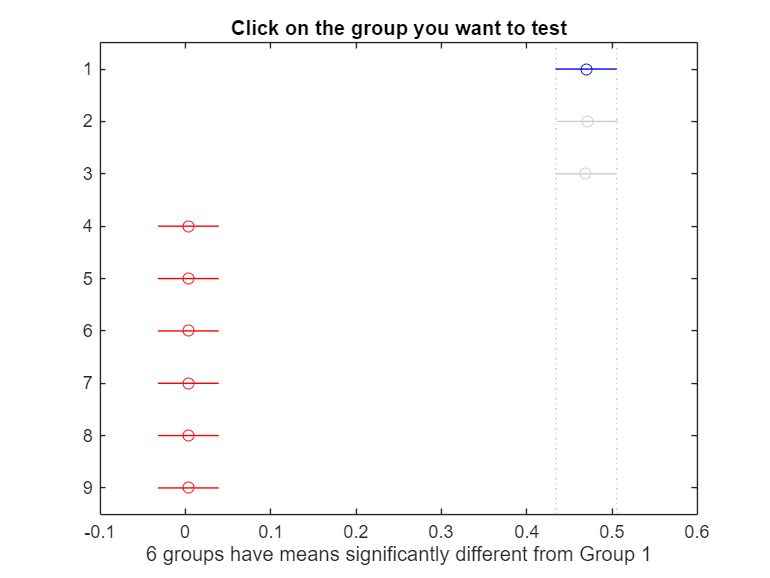

    Grupo1    Grupo2    Lower_CI        Diff        Upper_CI      PValue  
    ______    ______    _________    ___________    ________    __________

      1         2       -0.072558     -0.0011943    0.070169             1
      1         3       -0.071093     0.00027113    0.071635             1
      1         4         0.39482        0.46619     0.53755    7.6016e-34
      1         5         0.39487        0.46623     0.53759    7.5513e-34
      1         6         0.39485        0.46622     0.53758    7.5651e-34
      1         7         0.39479        0.46616     0.53752    7.6343e-34
      1         8         0.39481        0.46617     0.53754    7.6152e-34
      1         9          0.3948        0.46617     0.53753    7.6215e-34
      2         3       -0.069898      0.0014


Test de ANOVA para RMSE


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


    Grupo1    Grupo2    Lower_CI        Diff        Upper_CI      PValue  
    ______    ______    _________    ___________    ________    __________

      1         2       -0.072558     -0.0011943    0.070169             1
      1         3       -0.071093     0.00027113    0.071635             1
      1         4         0.39482        0.46619     0.53755    7.6016e-34
      1         5         0.39487        0.46623     0.53759    7.5513e-34
      1         6         0.39485        0.46622     0.53758    7.5651e-34
      1         7         0.39479        0.46616     0.53752    7.6343e-34
      1         8         0.39481        0.46617     0.53754    7.6152e-34
      1         9          0.3948        0.46617     0.53753    7.6215e-34
      2         3       -0.069898      0.0014


Test de ANOVA para MAE


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


    Grupo1    Grupo2    Lower_CI        Diff        Upper_CI      PValue  
    ______    ______    _________    ___________    ________    __________

      1         2       -0.072558     -0.0011943    0.070169             1
      1         3       -0.071093     0.00027113    0.071635             1
      1         4         0.39482        0.46619     0.53755    7.6016e-34
      1         5         0.39487        0.46623     0.53759    7.5513e-34
      1         6         0.39485        0.46622     0.53758    7.5651e-34
      1         7         0.39479        0.46616     0.53752    7.6343e-34
      1         8         0.39481        0.46617     0.53754    7.6152e-34
      1         9          0.3948        0.46617     0.53753    7.6215e-34
      2         3       -0.069898      0.0014

% Lista de métricas a evaluar
metricNames = {'MSE', 'RMSE', 'MAE'};

% Aplicar Kruskal-Wallis para cada métrica
for m = 1:numel(metricNames)
    metricName = metricNames{m};
    
    metricData = metricsSVM_DATOS1.MSE(:,:,1);
    numFolds = size(metricData,1);
    numModels = size(metricData,2);
    
    y = metricData(:);
    group = repelem(1:numModels, numFolds)';

    % Aplicamos el test de ANOVA
    [p,~,stats] = anova1(y, group, 'off');  % 'off' para evitar gráficos automáticos

    % Mostramos el resultado del test
    fprintf('\nTest de ANOVA para %s\n', metricName);
    fprintf('P-valor: %.4f\n', p);


    % Si hay diferencias significativas, realizamos comparaciones múltiples
    if p < 0.05
        fprintf('Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...\n');
        
        % Comparaciones múltiples usando multcompare
        figure;
        title(sprintf('Comparaciones múltiples para %s', metricName));
        [c,~,~,gnames] = multcompare(stats, 'CType', 'bonferroni');  % Puedes probar 'tukey-kramer'
        
        % Mostrar tabla de comparaciones múltiples
        disp(array2table(c, 'VariableNames', {'Grupo1', 'Grupo2', 'Lower_CI', 'Diff', 'Upper_CI', 'PValue'}));
    else
        fprintf('No se encontraron diferencias significativas entre los modelos para %s.\n', metricName);
    end
end

Hay diferencias significativas entre los SVM con kernel lineal y polinomila, sin embargo, entre el polinomial y el gaussiano no existen diferencias estadísticamente significativas, por lo que el modelo seleccionado sería el SVM4 (kernel gaussiano C=1), ya que tampoco existen diferencias entre distintos niveles del parámetro C.

 Entrenamos modelo con ventana tamaño 10

% Hiperparámetros
boxConstraint = [1, 3, 5];
kernelFunctions = {'linear', 'gaussian', 'polynomial'};
number_reps = 3;
K = 10;

[metricsSVM_DATOS2, combinaciones] = get_metricsSVM(INPUTS2, OUTPUTS2, boxConstraint, kernelFunctions, number_reps, K)

metricsSVM_DATOS2 = struct with fields:
     MSE: [10×9×3 double]
    RMSE: [10×9×3 double]
     MAE: [10×9×3 double]


combinaciones =      1     1
     3     1
     5     1
     1     2
     3     2
     5     2
     1     3
     3     3
     5     3


% Promediar sobre folds y repeticiones
Mean_MSE_final = squeeze(mean(mean(metricsSVM_DATOS2.MSE, 1), 3));
Std_MSE_final  = squeeze(std(reshape(metricsSVM_DATOS2.MSE, K*number_reps, []), 0, 1));

Mean_RMSE_final = squeeze(mean(mean(metricsSVM_DATOS2.RMSE, 1), 3));
Std_RMSE_final  = squeeze(std(reshape(metricsSVM_DATOS2.RMSE, K*number_reps, []), 0, 1));

Mean_MAE_final = squeeze(mean(mean(metricsSVM_DATOS2.MAE, 1), 3));
Std_MAE_final  = squeeze(std(reshape(metricsSVM_DATOS2.MAE, K*number_reps, []), 0, 1));

mostrarResumenSVM_Regresion(combinaciones, kernelFunctions, ...
    Mean_MSE_final, Std_MSE_final, ...
    Mean_RMSE_final, Std_RMSE_final, ...
    Mean_MAE_final, Std_MAE_final);

    Modelo     BoxConstraint       Kernel          MSE        MSE_std        RMSE      RMSE_std       MAE        MAE_std 
    _______    _____________    ____________    _________    __________    ________    _________    ________    _________

    "SVM 1"          1          "linear"          0.41765      0.051968     0.64495      0.03979     0.50192      0.02784
    "SVM 2"          3          "linear"          0.41264    0.00097522     0.64116    0.0060247     0.49897    0.0035822
    "SVM 3"          5          "linear"          0.41451    0.00027205     0.64242     0.002302     0.50044    0.0021375
    "SVM 4"          1          "gaussian"      0.0063787      0.056659    0.079724

% Almacenar las métricas para la primera repetición

metricsSVM_DATOS2_1 = struct('MSE', metricsSVM_DATOS2.MSE(:,:,1), ...
                    'RMSE', metricsSVM_DATOS2.RMSE(:,:,1), ...
                    'MAE', metricsSVM_DATOS2.MAE(:,:,1));


Test de ANOVA para MSE


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


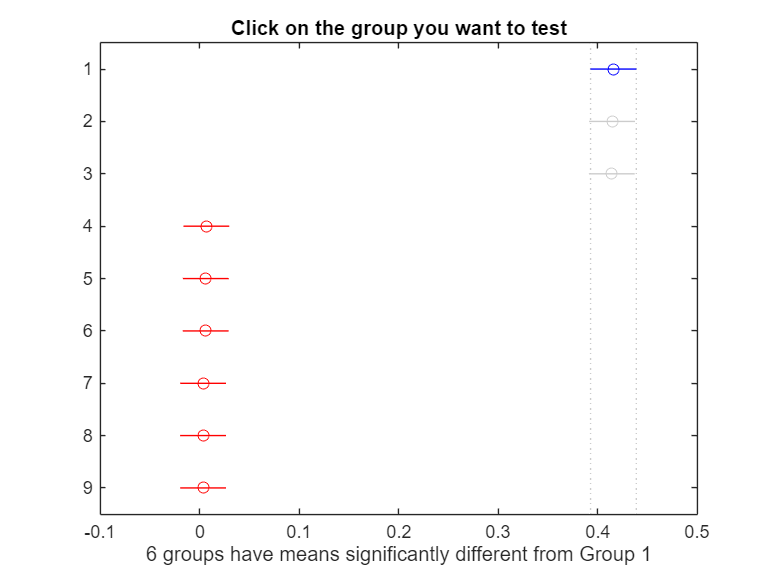

    Grupo1    Grupo2    Lower_CI        Diff       Upper_CI      PValue  
    ______    ______    _________    __________    ________    __________

      1         2       -0.044707     0.0013434    0.047394             1
      1         3       -0.044392     0.0016587    0.047709             1
      1         4         0.36291       0.40896     0.45501    1.9799e-43
      1         5         0.36343       0.40948     0.45553     1.804e-43
      1         6         0.36357       0.40962     0.45568    1.7562e-43
      1         7         0.36611       0.41216     0.45821    1.1118e-43
      1         8         0.36616       0.41222     0.45827       1.1e-43
      1         9         0.36619       0.41224     0.45829     1.096e-43
      2         3       -0.045735    0.00031535    0.04


Test de ANOVA para RMSE


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


    Grupo1    Grupo2    Lower_CI        Diff       Upper_CI      PValue  
    ______    ______    _________    __________    ________    __________

      1         2       -0.044707     0.0013434    0.047394             1
      1         3       -0.044392     0.0016587    0.047709             1
      1         4         0.36291       0.40896     0.45501    1.9799e-43
      1         5         0.36343       0.40948     0.45553     1.804e-43
      1         6         0.36357       0.40962     0.45568    1.7562e-43
      1         7         0.36611       0.41216     0.45821    1.1118e-43
      1         8         0.36616       0.41222     0.45827       1.1e-43
      1         9         0.36619       0.41224     0.45829     1.096e-43
      2         3       -0.045735    0.00031535    0.04


Test de ANOVA para MAE


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


    Grupo1    Grupo2    Lower_CI        Diff       Upper_CI      PValue  
    ______    ______    _________    __________    ________    __________

      1         2       -0.044707     0.0013434    0.047394             1
      1         3       -0.044392     0.0016587    0.047709             1
      1         4         0.36291       0.40896     0.45501    1.9799e-43
      1         5         0.36343       0.40948     0.45553     1.804e-43
      1         6         0.36357       0.40962     0.45568    1.7562e-43
      1         7         0.36611       0.41216     0.45821    1.1118e-43
      1         8         0.36616       0.41222     0.45827       1.1e-43
      1         9         0.36619       0.41224     0.45829     1.096e-43
      2         3       -0.045735    0.00031535    0.04

% Lista de métricas a evaluar
metricNames = {'MSE', 'RMSE', 'MAE'};

% Aplicar Kruskal-Wallis para cada métrica
for m = 1:numel(metricNames)
    metricName = metricNames{m};
    
    metricData = metricsSVM_DATOS2.MSE(:,:,1);
    numFolds = size(metricData,1);
    numModels = size(metricData,2);
    
    y = metricData(:);
    group = repelem(1:numModels, numFolds)';

    % Aplicamos el test de ANOVA
    [p,~,stats] = anova1(y, group, 'off');  % 'off' para evitar gráficos automáticos

    % Mostramos el resultado del test
    fprintf('\nTest de ANOVA para %s\n', metricName);
    fprintf('P-valor: %.4f\n', p);

    % Si hay diferencias significativas, realizamos comparaciones múltiples
    if p < 0.05
        fprintf('Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...\n');
        
        % Comparaciones múltiples usando multcompare
        figure;
        title(sprintf('Comparaciones múltiples para %s', metricName));
        [c,~,~,gnames] = multcompare(stats, 'CType', 'bonferroni');  % Puedes probar 'tukey-kramer'
        
        % Mostrar tabla de comparaciones múltiples
        disp(array2table(c, 'VariableNames', {'Grupo1', 'Grupo2', 'Lower_CI', 'Diff', 'Upper_CI', 'PValue'}));
    else
        fprintf('No se encontraron diferencias significativas entre los modelos para %s.\n', metricName);
    end
end

Hay diferencias significativas entre los SVM con kernel lineal y polinomila, sin embargo, entre el polinomial y el gaussiano no existen diferencias estadísticamente significativas, por lo que el modelo seleccionado sería el SVM4 (kernel gaussiano C=1), ya que tampoco existen diferencias entre distintos niveles del parámetro C.

Ahora comprobamos si existen diferencias entre los dos modelos que hemos escogido con distinto tamaño de ventana.

datos1_SVM4 = struct('MSE', metricsSVM_DATOS1_1.MSE(:,4), ...
                    'RMSE', metricsSVM_DATOS1_1.RMSE(:,4), ...
                    'MAE', metricsSVM_DATOS1_1.MAE(:,4));

datos2_SVM4 = struct('MSE', metricsSVM_DATOS2_1.MSE(:,4), ...
                    'RMSE', metricsSVM_DATOS2_1.RMSE(:,4), ...
                    'MAE', metricsSVM_DATOS2_1.MAE(:,4));

Test de Wilcoxon

% Test de Wilcoxon para MSE
[p_MSE, ~, ~] = signrank(datos1_SVM4.MSE, datos2_SVM4.MSE);
fprintf('MSE: p = %.4f', p_MSE);

MSE: p = 0.0020


% Test de Wilcoxon para RMSE
[p_RMSE, ~, ~] = signrank(datos1_SVM4.RMSE, datos2_SVM4.RMSE);
fprintf('RMSE: p = %.4f', p_RMSE);

RMSE: p = 0.0020


% Test de Wilcoxon para MAE
[p_MAE, ~, ~] = signrank(datos1_SVM4.MAE, datos2_SVM4.MAE);
fprintf('MAE: p = %.4f', p_MAE);

MAE: p = 0.0020

Está claro que el modelo con un tamaño de ventana de 5 es mejor para predecir valores. Ya que todas las métricas presentan una disminución estadísticamente significativas respecto al modelo entrenado con un tamaño de ventana de 10.

Entrenamiento con el mejor modelo (tamaño de ventana: 5, c=1, kernel=gaussiana)

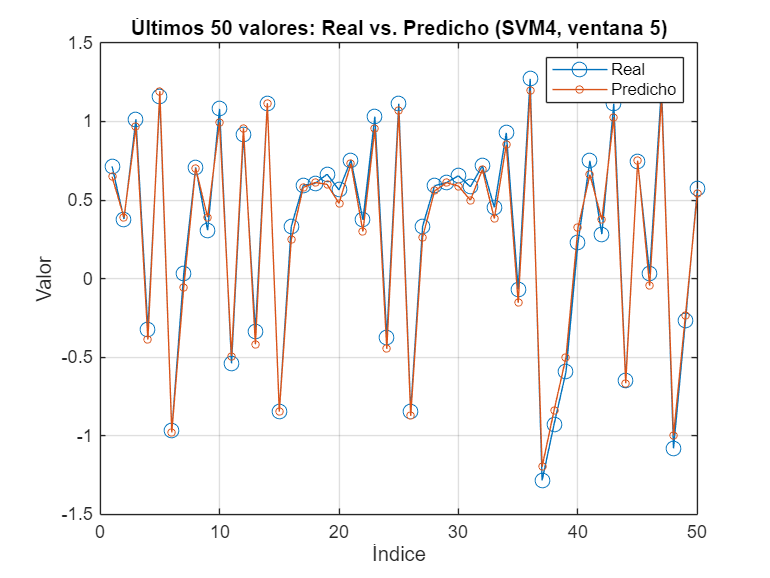

% Tomar las últimas 50 muestras reales de la serie original
x_last50_real = x(end-49:end);

% Crear todo el conjunto de ventanas tamaño 5
[INPUTS1_full, OUTPUTS1_full] = slidingwindow(x, 5);

% Excluir las últimas 50 muestras objetivo del entrenamiento
% (no se deben usar las 50 últimas ventanas que las generan)
num_total = size(INPUTS1_full, 1);
idx_train = 1:(num_total - 50);       % Todo menos las últimas 50

% Preparar conjuntos de entrenamiento y prueba
X_train = INPUTS1_full(idx_train, :);
Y_train = OUTPUTS1_full(idx_train);
X_test = INPUTS1_full(end-49:end, :);  % Las últimas 50 entradas que generan las predicciones
Y_test = OUTPUTS1_full(end-49:end);    % Verdaderos valores esperados

% Entrenar el mejor modelo (ejemplo con SVM, cámbialo si usas NN)
best_model = fitrsvm(X_train, Y_train, ...
    'BoxConstraint', 1, ...
    'KernelFunction', 'gaussian');

% Predecir los últimos 50 valores
Y_pred = predict(best_model, X_test);

% === VISUALIZACIÓN ===
figure;
plot(1:50, Y_test, '-o', 'MarkerSize', 8, 'DisplayName', 'Real');
hold on;
plot(1:50, Y_pred, '-o', 'MarkerSize', 4, 'DisplayName', 'Predicho');
title('Últimos 50 valores: Real vs. Predicho (SVM4, ventana 5)');
xlabel('Índice');
ylabel('Valor');
legend;
grid on;
hold off;


% (Opcional) Cálculo del RMSE sobre los últimos 50 valores
rmse_ultimos50 = sqrt(mean((Y_test - Y_pred).^2));
fprintf("RMSE en las últimas 50 muestras: %.4f\n", rmse_ultimos50);

RMSE en las últimas 50 muestras: 0.0635
